## Spatial Arm

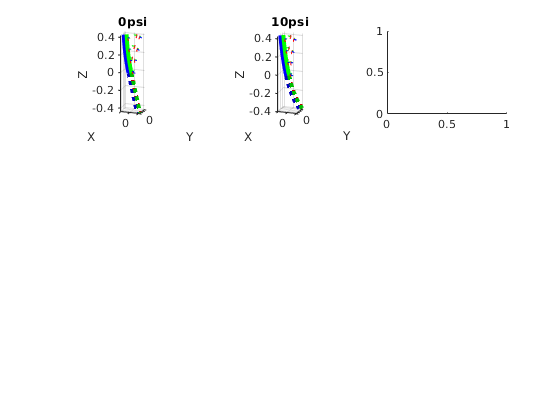

Testing with bag: localized-0psi_2021-12-15-21-47-07.bag
Testing with bag: localized-10psi_2021-12-15-21-46-29.bag


Index exceeds the number of array elements (1).

Error in get_tagslam_bag (line 19)
    bag = bags_at_pressure(bag_choice);

%% Define where to look for rosbag files
project_root = "~/tagslam_ws/tagslam_root/src/continuum_mocap";
experiment_name = "spatial_arm_1";

%% Parameterize tag locations
% ids of tags along the arm (and the order that we will store them in)
experiment_tags = [15 13 12 9 14 8 7 6]; % Tags 6 to 9 
base_tag_id = 15;

% the muscles that these muscles are attached to (in the same order) 
tag_muscle_ids = [1 1 1 1 2 2 2 2]; % List of muscle ids that the tags are attached to, in order

% Define t_tags: Percentage of tag position along total length of arm
% Tag in the middle of arm: t = 0.5
muscle_length_cm = 18 * 2.54;
muscle_spacing_cm = 13;
base_offset_cm = 2;
t_tags = ([0, 1, 2, 3, 0, 1, 2, 3] * muscle_spacing_cm + base_offset_cm) / muscle_length_cm;

% Pressures corresponding to each experiment bag file in order
experiment_pressures = [0 10 20 30 40 50 60];

%% Parameterize the arm
rho = 0.75 * 0.0254; % M, Radius
muscle_angle = 0;

%% Construct pose matrices
% Transformations from world frame to each muscle

% Posese of muscle in world frame
% Muscles are arranged in equilateral triangle with radius rho
g_muscles = Arm3D.generate_g_muscles(rho, g_default_muscle, 3, muscle_angle);

% Set position of first muscle to actually be at the origin
% We want to shift *everything* uniformly regardless of its pose, therefore
% it'll be a left-action:
% g_shift * g_1 = g_neutral
% Therefore g_shift = g_neutral * inv(g_1)
% Additionally, we rotate by a global 180deg so that all 3 muscles are
% aligned correctly
g_muscle_shift = g_default_muscle * inv(g_muscles{1});

% Then left-apply g_shift to all transformations
g_o = g_muscle_shift * g_default_muscle;
g_muscles = cellfun(@(g_muscle) g_muscle_shift * g_muscle, g_muscles, 'uniformoutput', false);

fig = figure();
ax = axes(fig);

mat_h_o_model = zeros(6, length(experiment_pressures));
mat_h_o_fit = zeros(6, length(experiment_pressures));
for i = 1 : length(experiment_pressures)
    subplot(3, 3, i)
    bag = get_tagslam_bag(experiment_name, experiment_pressures(i), bag_choice(i));
    
    [mat_h_o_model(:, i), mat_h_o_fit(:, i)] = ...
        plot_exp_comparison_3d(bag, experiment_pressures(i), experiment_tags, tag_muscle_ids, t_tags, base_tag_id, g_o, g_muscles);
    title(sprintf("%dpsi", experiment_pressures(i)))
end

sgtitle("Spatial Arm Bending: Measured (solid) vs Model (dash)")

figure()
set(gcf, 'position', [0, 0, 1200, 400])
subplot(1, 2, 1)
hold on
plot(experiment_pressures, mat_h_o_fit(6, :), 'b', 'linewidth', 3)
plot(experiment_pressures, mat_h_o_model(6, :), 'r:', 'LineWidth', 3)
legend(["Experiment", "Model"])
title("Pressure vs Curvature")
xlabel("Pressure (psi)")
ylabel("Curvature (1/m)")
grid on

subplot(1, 2, 2)
plot(experiment_pressures, mat_h_o_fit(6, :) - mat_h_o_model(6, :), 'linewidth', 3);
grid on
title("Curvature error")
xlabel("Pressure (psi)")
ylabel("Curvature Error (1/m)")
sgtitle("Spatial arm metrics")

## Helical Arm

%% Define where to look for rosbag files
project_root = "~/tagslam_ws/tagslam_root/src/continuum_mocap";
experiment_name = "feb_2022/spatial_3muscle";

%% Parameterize tag locations
% ids of tags along the arm (and the order that we will store them in)
experiment_tags = [6 7 8 15 10 11 14 9]; % Tags 6 to 9 
base_tag_id = 10;

% the muscles that these muscles are attached to (in the same order) 
tag_muscle_ids = [3 3 3 3 1 1 1 1]; % List of muscle ids that the tags are attached to, in order

% Define t_tags: Percentage of tag position along total length of arm
% Tag in the middle of arm: t = 0.5
muscle_length_cm = 18 * 2.54;
muscle_spacing_cm = 13;
base_offset_cm = 2;
t_tags = ([0, 1, 2, 3, 0, 1, 2, 3] * muscle_spacing_cm + base_offset_cm) / muscle_length_cm;

% Pressures corresponding to each experiment bag file in order
experiment_pressures = [0 10 15 20 25 30 35 40 45 50 55 60];
bag_choice = [2 2 2 1 1 1 1 1 2 1 2 1];

%% Parameterize the arm
rho = 0.75 * 0.0254; % M, Radius
muscle_angle = 0;

%% Construct pose matrices
% Transformations from world frame to each muscle

g_default_muscle_original = SE3(eul2rotm([0, pi/2, 0], 'xyz'), [0 0 0]);
g_default_muscle = SE3(eul2rotm([0, pi/2 + deg2rad(4), 0], 'xyz'), [0 0 0]); % Frame corresponding to a muscle at the origin, pointing down

% Posese of muscle in world frame
% Muscles are arranged in equilateral triangle with radius rho
g_muscles = Arm3D.generate_g_muscles(rho, g_default_muscle_original, 3, muscle_angle);

% Set position of first muscle to actually be at the origin
% We want to shift *everything* uniformly regardless of its pose, therefore
% it'll be a left-action:
% g_shift * g_1 = g_neutral
% Therefore g_shift = g_neutral * inv(g_1)
% Additionally, we rotate by a global 180deg so that all 3 muscles are
% aligned correctly
g_muscle_shift = g_default_muscle_original * inv(g_muscles{1});

% Then left-apply g_shift to all transformations
g_o = g_muscle_shift * g_default_muscle_original;
g_muscles = cellfun(@(g_muscle) g_muscle_shift * g_muscle, g_muscles, 'uniformoutput', false);

model_arm = Arm3D(g_o, g_muscles, contraction_fit(0), 'plot_unstrained', false);
model_arm.n_spacers = 0;

fig = figure();
ax = axes(fig);

mat_h_o_model = zeros(6, length(experiment_pressures));
mat_h_o_fit = zeros(6, length(experiment_pressures));
for i = 1 : length(experiment_pressures)
    subplot(3, 4, i)
    bag = get_tagslam_bag(experiment_name, experiment_pressures(i), bag_choice(i));
    
    [mat_h_o_model(:, i), mat_h_o_fit(:, i)] = ...
        plot_exp_comparison_3d(bag, experiment_pressures(i), experiment_tags, tag_muscle_ids, t_tags, base_tag_id, model_arm);
    title(sprintf("%dpsi", experiment_pressures(i)))
end

Testing with bag: localized-0psi_2022-02-06-19-55-07.bag
Testing with bag: localized-10psi_2022-02-06-19-54-34.bag
Testing with bag: localized-15psi_2022-02-06-19-53-50.bag
Testing with bag: localized-20psi_2022-02-06-19-39-37.bag
Testing with bag: localized-25psi_2022-02-06-19-40-10.bag
Testing with bag: localized-30psi_2022-02-06-19-42-51.bag
Testing with bag: localized-35psi_2022-02-06-19-43-32.bag
Testing with bag: localized-40psi_2022-02-06-19-44-09.bag
Testing with bag: localized-45psi_2022-02-06-19-50-25.bag
Testing with bag: localized-50psi_2022-02-06-19-45-20.bag
Testing with bag: localized-55psi_2022-02-06-19-49-19.bag
Testing with bag: localized-60psi_2022-02-06-19-46-44.bag


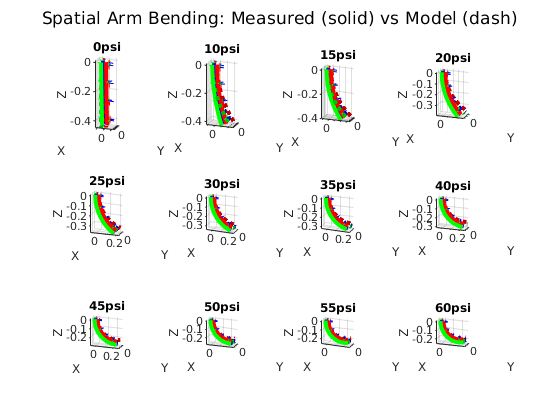

sgtitle("Spatial Arm Bending: Measured (solid) vs Model (dash)")

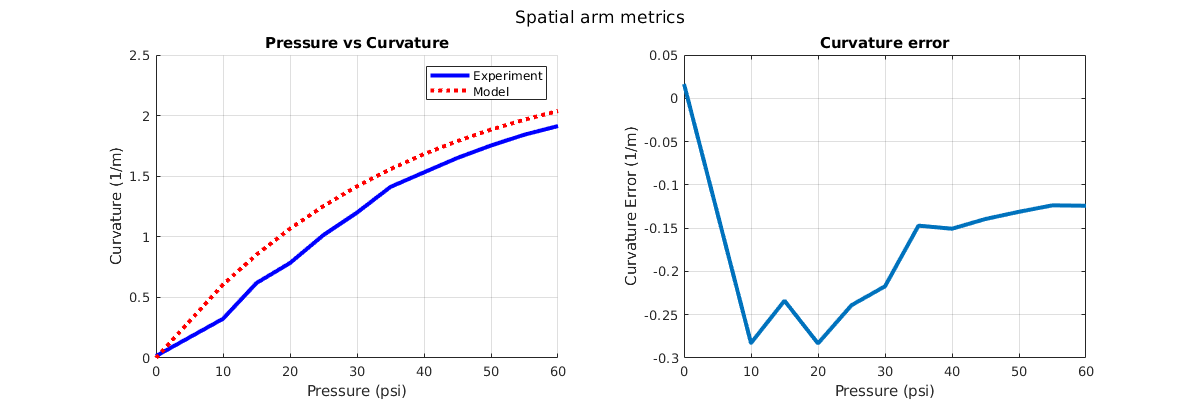


figure()
set(gcf, 'position', [0, 0, 1200, 400])
subplot(1, 2, 1)
hold on

%plot(experiment_pressures, mat_h_o_fit(6, :), 'b', 'linewidth', 3)
%plot(experiment_pressures, mat_h_o_model(6, :), 'r:', 'LineWidth', 3)

plot(experiment_pressures, vecnorm(mat_h_o_fit(4:6, :)), 'b', 'linewidth', 3)
plot(experiment_pressures, vecnorm(mat_h_o_model(4:6, :)), 'r:', 'LineWidth', 3)
legend(["Experiment", "Model"])
title("Pressure vs Curvature")
xlabel("Pressure (psi)")
ylabel("Curvature (1/m)")
grid on

subplot(1, 2, 2)
plot(experiment_pressures, vecnorm(mat_h_o_fit(4:6, :)) - vecnorm(mat_h_o_model(4:6, :)), 'linewidth', 3);
%plot(experiment_pressures, mat_h_o_fit(6, :) - mat_h_o_model(6, :), 'linewidth', 3);
grid on
title("Curvature error")
xlabel("Pressure (psi)")
ylabel("Curvature Error (1/m)")
sgtitle("Spatial arm metrics")